## Homework 4: Space Vehicles and Orbital Dynamics

#### Authors:

- Jaume Manresa Rigo (100461930)

- Jorge Cortés de Jesús (100428594)

clear; clc; 
close all;

### Introduction

The objective of this homework is to explore a family of Lyapunov closed periodic orbits contained in the *xy* plane of the Circular Restricted Three-Body Problem (CR3BP) with $\mu^{\ast } =0\ldotp 001$, around the Lagrange libration point $L_1$. This is a very relevant problem in astrodynamics for interplanetary spaceflights and general celestial mechanics. CR3BP assumes that: 

- $m^{P_1 } >m^{P_2 } \gg m^{P_3 }$. Thus, the motion of $P_1$ and $P_2 \;$(primaries) is assumed to be unaffected by $P_3$.

- The primaries orbit the center of mass in circles, i.e. the motion of the primaries is an unperturbed 2BP.

mustar = 0.001;

The analysis will be performed in the synodic (rotating) reference frame. 

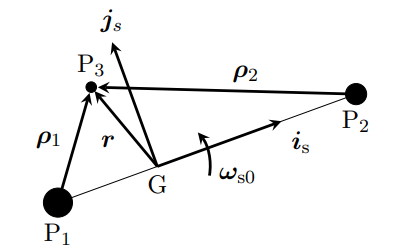

The full nonlinear equations will be employed.

$\ddot{x} =-\frac{1-\mu^{\ast } }{\rho_1^3 }\left(x+\mu^{\ast } \right)-\frac{\mu^{\ast } }{\rho_2^3 }\left(x+\mu^{\ast } -1\right)+x+2\dot{y}$,

$\ddot{y} =-\frac{1-\mu^{\ast } }{\rho_1^3 }y-\frac{\mu^{\ast } }{\rho_2^3 }y+y-2\dot{x}$,

Where $\rho_1^2 ={\left(x+\mu^{\ast } \right)}^2 +y^2 +z^2$, and $\rho_2^3 ={\left(x+\mu^{\ast } -1\right)}^2 +y^2 +z^2$ are the normalized magnitude of the distance vector from P1 and P2 to P3, respectively.

### Part (a)

To begin, the position of $L_1$ will be obtained. From theory, it is known that this specific point, along with $L_2$ and $L_3$, will be collinear, which means that its position will lie in the x-axis. Furthermore, knowing that a Lagrange point is an equilibrium position and taking the first equation the expression for $x_{L_1 }$ is found.


$$0=\frac{1-\mu^{\ast } }{\rho_1^3 }\left(x_{L_1 } +\mu^{\ast } \right)-\frac{\mu^{\ast } }{\rho_2^3 }\left(x_{L_1 } +\mu^{\ast } -1\right)+x_{L_1 }$$


where $\rho_1 =\left|x_{L_1 } +\mu^{\ast } \right|$ and $\rho_2 =\left|x_{L_1 } +\mu^{\ast } -1\right|$. 

To computation of $x_{L_1 }$ will utilize the bult-in Matlab function *fzero. *It is essential to carefully select an initial guess ($x_0$) to ensure that the solver actually finds $x_{L_1 }$ instead of $x_{L_2 }$ or $x_{L_3 }$. Given that $L_1$ will be located between $P_1$ and $P_2 \;$, the non-dimensional position of both bodies is calculated, finding the mean value and using it as $x_0$.


$$x_1 =-\mu^{\ast } ;\;\;\;\;\;x_2 =1-\mu^{\ast }$$



$$x_0 =\frac{x_1 +x_2 }{2}$$


x1 = -mustar;
x2 = 1-mustar;
x0 = (x1+x2)/2;

f = @(xL1) -(1-mustar)/abs(xL1+mustar)^3*(xL1+mustar) - mustar/abs(xL1-1+mustar)^3*(xL1-1+mustar) + xL1;
xL1 = fzero(f,x0);

fprintf('The position of the first Lagrange libration point (L1) is %f ',xL1);

The position of the first Lagrange libration point (L1) is 0.931287 

### Part (b)

In this section, a function *dX_dt = CR3BP(X,mustar) *that computes the derivatives of the state vector in the *xy* plane, $X={\left\lbrack x,y,\dot{x,} \dot{y} \right\rbrack }^T$, will be implemented. 

The function will follow a simple approach. First, $\rho_1$ and $\rho_2$ will be calculated. With these, the full nonlinear equations will be used to obtain the second time derivative of $x$and $y$. Then, the derivative of the state vector, $\dot{X} ={\left\lbrack \dot{x} ,\dot{y} ,\ddot{x} ,\ddot{y} \right\rbrack }^T$, is assigned as the output of the function.

### Part (c)

To continue, a function *[t,X] = RK4(f,times,X0)* that employs the standard Runge-Kutta 4th-order scheme to integrate the function *f = @(t,X) CR3BP(X,mustar), *from an initial condition *X0*, for the discrete time instants in the vector *times.*

Runge-Kutta are iterative methods that introduce points between $t_n \;$ and $t_{n+1}$ and evaluate the function at these intermediate points. The 4th-order RK method has the following form:

$U_1 =x_n$,

$U_2 =x_n +\frac{1}{2}\Delta t\cdot f\left(t_n ,U_1 \right)$,

$U_3 =x_n +\frac{1}{2}\Delta t\cdot f\left(t_n +\frac{\Delta t}{2},U_2 \right)$,

$U_4 =x_n +\Delta t\cdot f\left(t_n +\frac{\Delta t}{2},U_3 \right)$,


$$x_{n+1} =x_n +\frac{1}{6}\Delta t\left\lbrack \left.f\left(t_n ,U_1 \right)+2f\left(t_n +\frac{\Delta t}{2},U_2 \right)+2f\left(t_n +\frac{\Delta t}{2},U_3 \right)+f\left(t_n +\Delta t,U_4 \right)\right)\right\rbrack$$


Note that the output time vector *t *is equal to the vector times introduced as an input.

Once RK4 is implemented, the previously calculated position of the first Lagrange libration point, $x_{L_1 }$, will be used as an initial guess. As it is an equilibrium position ($\left.\dot{x} =\dot{y} =0\right)$ and is located at $y=0$, the initial guess will be $X_0 =$${\left\lbrack x_{L_1 } ,0,0,0\right\rbrack }^T$.

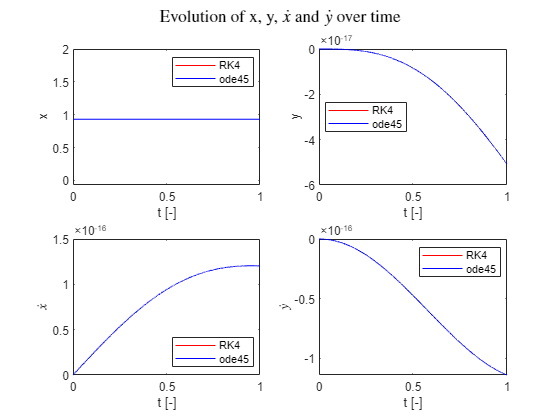

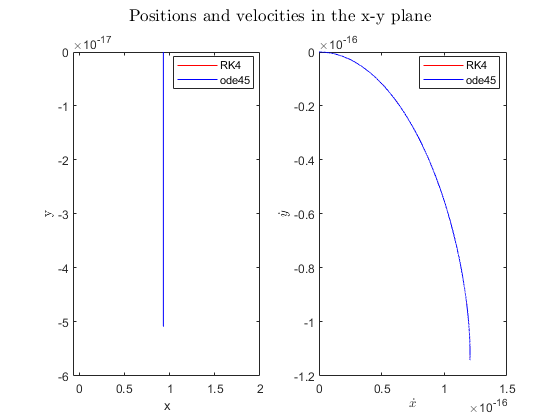

X0 = [xL1;0;0;0];
times = (0:1e-4:1)';

f = @(t,X) CR3BP(X,mustar);
[t,X] = RK4(f,times,X0);
[t_ode45,X_ode45] = ode45(f,times,X0);

examplePlots(t,X,t_ode45,X_ode45);

As expected, the evolution of x over time is constant, while the other parameters remain negligible. 

A random initial guess $X_0 =$${\left\lbrack {0\ldotp 5\cdot x}_{L_1 } ,-0\ldotp 3,0\ldotp 1,0\ldotp 7\right\rbrack }^T$ will now be introduced.

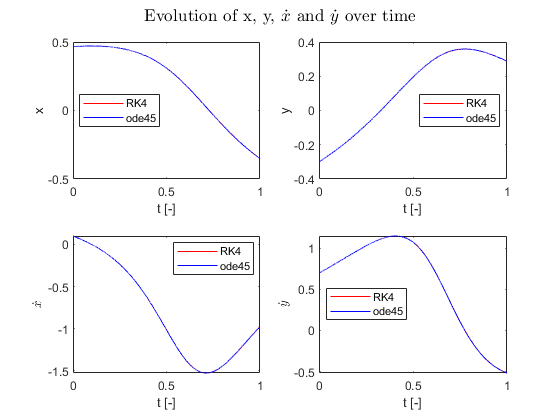

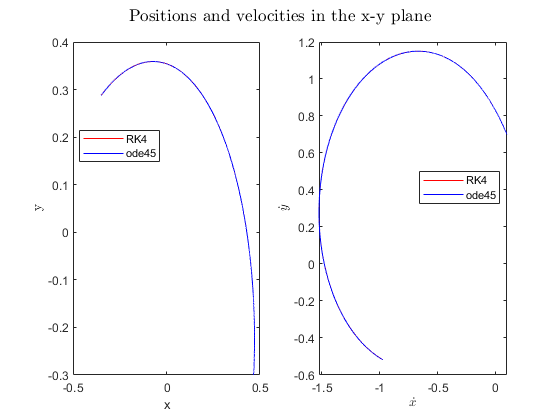

X0 = [0.5*xL1;-0.3;0.1;0.7];

[t,X] = RK4(f,times,X0);
[t_ode45,X_ode45] = ode45(f,times,X0);

examplePlots(t,X,t_ode45,X_ode45);

In both cases, the difference between using RK4 and ode45 is minimal.

### Part (d)

In this section, a shooting method will be created in order to calculate the final $x$ velocity of a given object when crosses the $y$ axis, starting at an initial position $\left(x_0 ,0\right)$ with an initial velocity vector $\left(\dot{x} ,\dot{y} \right)=\left(0,\dot{y_0 } \right)$. The condition for finding a solution is when the object crosses the $y$ axis, thus when $y\le 0$. As no predetermined time step has been provided, an analysis comparing the final $y$ values with different time steps has been performed. The results show, that the variation of $y_f$ with respect to $\Delta t$ gets reduced as the time step becomes smaller, that is the difference between the final $y$ value for $\Delta t=0\ldotp 001$ and $\Delta t=0\ldotp 0005$ becomes significantly small. One could decrease the time step indefinetly, however the time of execution of the code will also tend to infinity. Thus, it was found that a good compromise between speed and accuracy was for $\Delta t=0\ldotp 0005$.

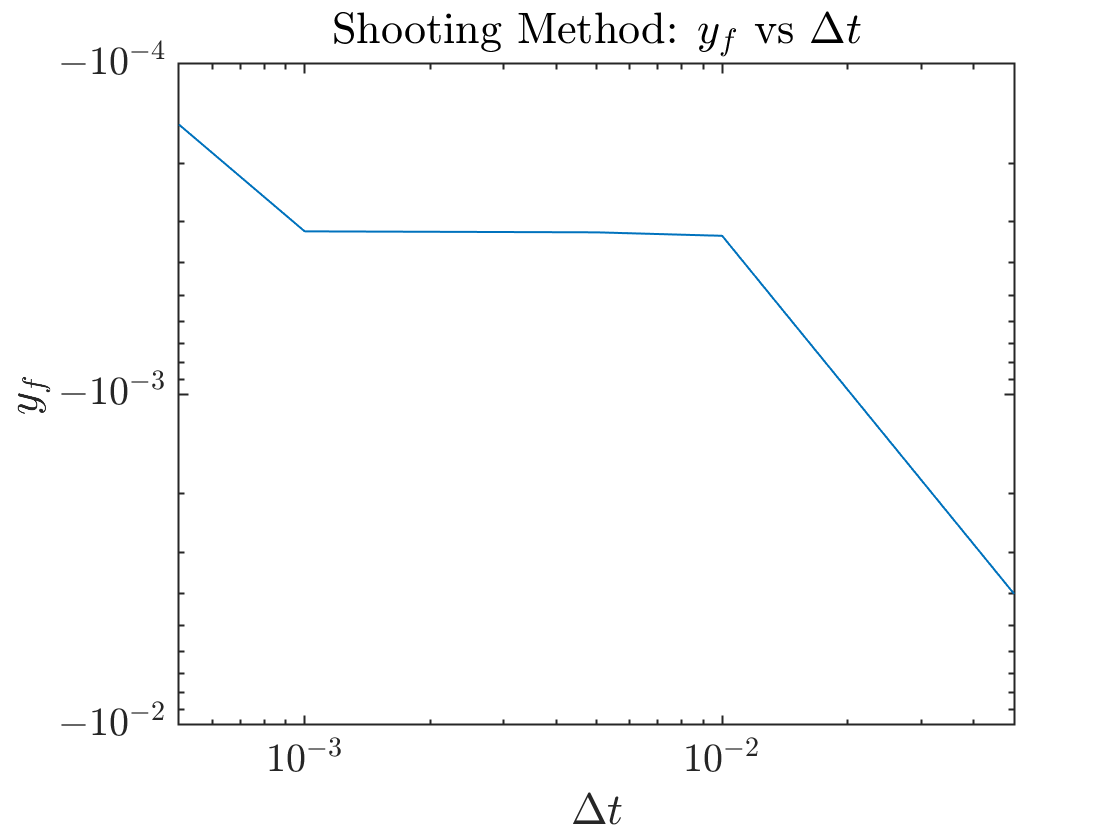

dt_vector = [0.05, 0.01, 0.01, 0.005, 0.001, 0.0005];

% Dt analysis 
PlotYfvsDt(X0(1), X0(4), mustar,dt_vector)

### Part (e)

In this final part, an algorithm is implemented in order to find solutions that result in single loop Lyapunov closed orbits contined in the $\mathrm{xy}$ plane of the CR3BP, at specific starting $x$ positions with respect to the L1 point (defined by an offset distance, $d$). The algorithm obeys the following structure:

- Set the **intial conditions**: the starting $x_0$ position is defined as $x_0 =x_{L_1 } -d$ where $d\in \left\lbrack 0\ldotp 010,\;0\ldotp 015,\;0\ldotp 020,\;0\ldotp 025,\;0\ldotp 030\right\rbrack$. The remaining inital condition is the $y$ velocity, $\dot{y_0 }$. The selection of such value is crucial in order to ensure convergence and Lyapunov closed orbits.

- **Secant and shooting method**: here the numerical *secant* method is used together with the *shoot* method in order to find an inital $y$ velocity such that the final $x$ velocity is $0$.

- **Repeat** the process for all $x_0$.

Given that the code was taking quite some time to execute, the variables were stored in a .*mat* file in order to be able to access them later on and continue with the development of the code more efficiently.

% Left and right boundaries for exploration of solutions with the secant method
% These have been selected manually (trial and error) to get propper results 
ydotL_vec = [0.085 0.138 0.171 0.191 0.205];
ydotR_vec = [0.088 0.139 0.172 0.192 0.206];

d = [0.01 0.015 0.02 0.025 0.03]; % distance to Lagrange Point (L1)
dt_secant = 10e-4; % time step used for secant method


for i = 1:length(d)
    x0 = xL1 - d(i); % distance to the left of the L1 point
    
    f = @(ydot0) shoot(x0,ydot0,mustar,dt_secant);
    ydotL = ydotL_vec(i);
    ydotR = ydotR_vec(i);
    
    % Secant method: finds ydot0 that makes x_dot component zero, when
    % crossing x-axis
    ydot0_sec = secant(f,ydotL,ydotR);
    
    xdotf(i) = shoot(x0,ydot0_sec,mustar,dt);
    
    % Save the data in order to plot it afterwards (this is done to avoid
    % to run the code as it takes a while)
    X = get_Xf(x0,ydot0_sec,mustar,dt); % Get all state vector for the trajectory
     
    % Save inital and final state vector in a data structure
    save X0XfinalAlld.mat % Save all data in a 
    X0XfinalAlld.X0(:,i) = [x0 0 0 ydot0_sec]'; % Save initial state vector as 
    X0XfinalAlld.Xfinal(:,i) = [X(end, 1); X(end, 2); xdotf(i); X(end, 3)]; % Final state vector
    
    % Save full trajectory state vector in a .mat file
    X_whole = ['Xd' num2str(i),'.mat'];
    save(X_whole,'X'); % save variable 
    
end

Once the orbits have been calculated, one can plot them by running the following procedure:

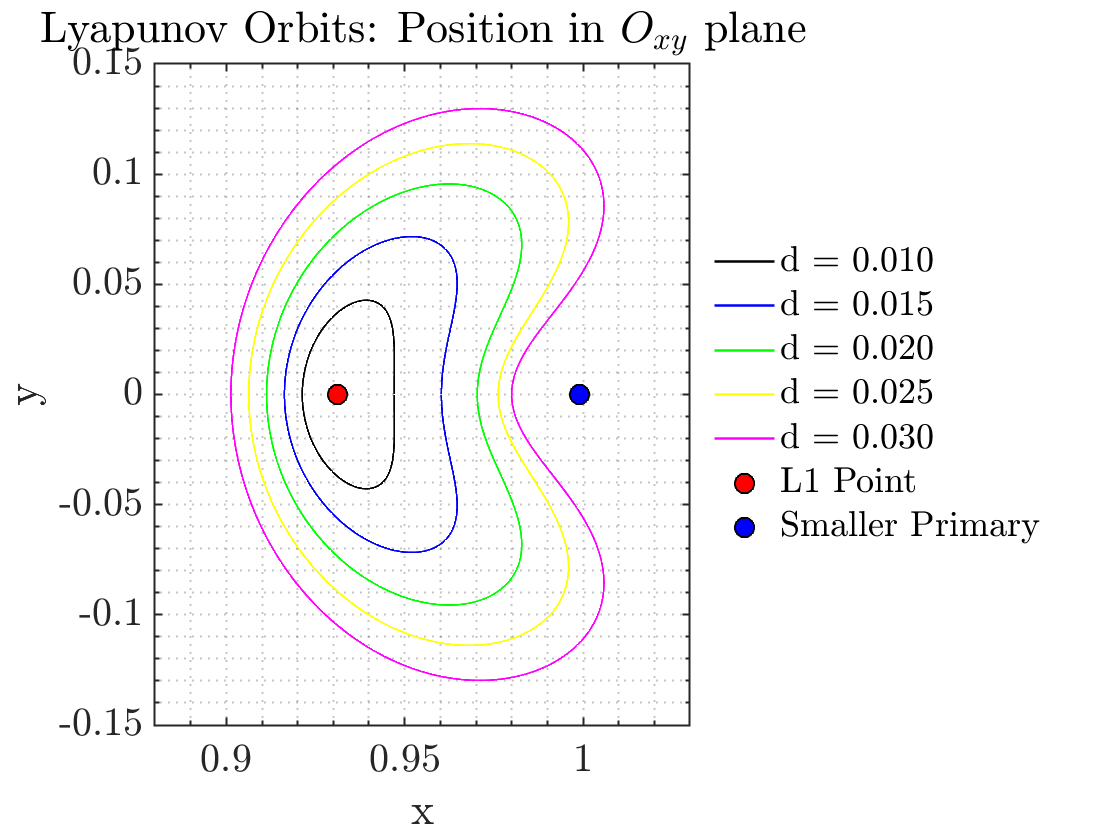

PlotSingleLoopOrbitsL1(xL1, d, mustar)

This graph shows the different Lyapunov Orbits for different starting positions and $y$ velocities. The shape of the orbits indicate that the greater $x_0$, the more deformed the resulting orbit will be, due to the gravity effect of the smaller primary body. Furthermore, there is a threshold point such that a satellite will go from orbiting the L1 point (Lyapunov Closed Orbits), to orbiting the smaller primary.

Given the unstable nature of the collinear Lagrange points, the problem is very sensitive to the initial conditions. If $\dot{y_0 }$ is too small, for the given starting position, convergence problems are likely to appear; and if $\dot{y_0 }$ is too big, then the resulting orbit is not a Lyapunov (as explained above). The values of such starting velocities were selected manually by trial and error using the *shoot* method and checking whether$\dot{\;x}$ experimented a change of sign and making sure that $x_f$ was in between $x_{L_1 }$ and $r_2$ (position of the smaller primary). If the initial conditions were selected correctly, the unstable solution of the differential equations cancelled out (positive eigenvalue, responsible for the exponentially growing motion away from the Lagrange point) thus making it possible to orbit around the unstable collinear point.

Furthermore, as only one period was considered, no significant perturbations were observed. However, if the solution were to be integrated over a much longer orbital period, one could see that even the smallest deviation from an ideal initial condition and/or any perturbation during the orbital phase would drift the orbit away from the Lagrange point, i.e. the unstable nature of the orbit would be manifested.

### Conclusion and Remarks

Following with the same procedure as the previous labs, GitHub was used in order to have a common repository where the different changes made to the code were updated. This made the process of carrying out this laboratory much more efficient. Copilot was not used during this laboratory, as no use cases were considered. Whenever a code question or doubt was raised, Google was the go to answer.